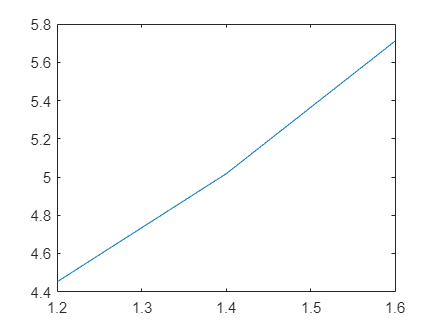

clc;
clear;

%Declaro mi ecuación diferencial
f=@(x,y)x.*sqrt(y); 
x0=1; %condición inicial f(1)=4
y0=4;
xf=1.6;
h=0.2;%Tamaño de salto

%Usando el método de Runge Kutta de orden 4
vectorX = x0:h:xf-h;
x = zeros(size(vectorX));
y = zeros(size(vectorX));
for i=1:length(vectorX)
k1=f(x0,y0);
k2=f(x0+(1/2)*h,y0+(1/2)*h*k1);
k3=f(x0+(1/2)*h,y0+(1/2)*h*k2);
k4=f(x0+h,y0+h*k3);
y0=y0+(h/6)*(k1+2*k2+2*k3+k4);
x0=x0+h;
x(i)=x0;
y(i)=y0;
end
plot(x,y)


disp("En x: "+string(x0)+" el valor de y es: "+string(y0)) %imprimiendo el resultado

En x: 1.6 el valor de y es: 5.7121
